# Using GPT-4 with Vision

This script demonstrates a chat interaction with the OpenAI Chat Completions API about images passed as part of the message. You must have access to GPT-4 Turbo with Vision, `gpt-4-vision-preview`, to run this example. 

% Use the valid API key from the paid OpenAI API account
loadenv(".env")
addpath('..') 

## Asking questions about an image using a URL

Load the sample image from Wikipedia.

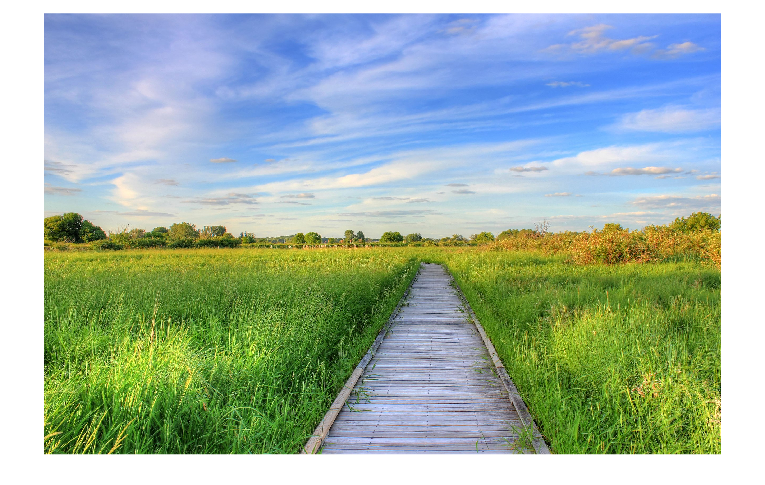

image_url = 'https://upload.wikimedia.org/wikipedia/commons/thumb/d/dd/Gfp-wisconsin-madison-the-nature-boardwalk.jpg/2560px-Gfp-wisconsin-madison-the-nature-boardwalk.jpg';
im = imread(image_url);
imshow(im)

Ask questions about the image with the URL. Select `gpt-4-vision-preview` model to create a chat object

chat = openAIChat("You are an AI assistant.", ModelName="gpt-4-vision-preview"); 

Create a message and pass the image url along with the prompt.

messages = openAIMessages;
messages = addUserMessageWithImages(messages,"What is in the image?",string(image_url));

Generate a response. By default, the model returns a very short reponse. To override it, set `MaxNumTokens` to 4096 or lower. 

[txt,~,response] = generate(chat,messages,MaxNumTokens=4096);
if response.StatusCode == "OK"
    wrappedText = wrapText(txt)
else
    response.Body.Data.error
end

wrappedText =     "The image depicts a tranquil natural landscape, featuring a wooden boardwalk extending through a lush green meadow.
     The boardwalk serves as a path that allows for exploration while preserving the natural environment.
     The grass on either side is tall and vibrant, indicating that the photo was likely taken in late spring or summer.
     The sky is partly cloudy, with a few streaks of cirrus clouds, suggesting fine weather.
     Trees can be seen in the distance, adding to the diversity of the greenery and contributing to the overall serene setting."


## Asking questions about an image from a file

Load a sample image from built-in datasets.

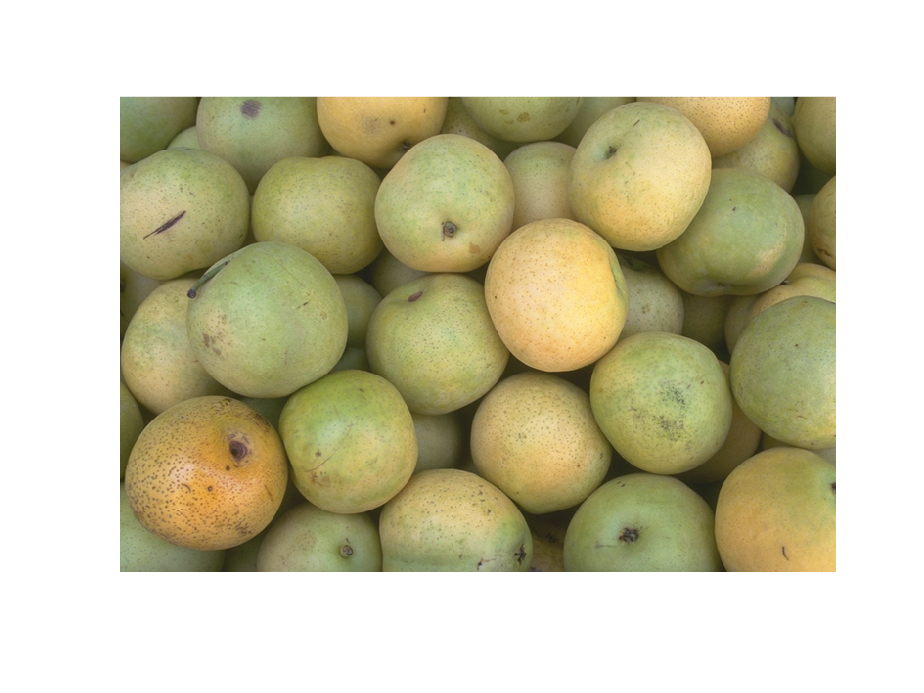

image_path = "pears.png";
im = imread(image_path);
imshow(im)

Ask questions about the image with the file path of the image. 

messages = openAIMessages;
messages = addUserMessageWithImages(messages,"What is in the image?",image_path);

Generate a response. 

[txt,message,response] = generate(chat,messages,MaxNumTokens=4096);
if response.StatusCode == "OK"
    wrappedText = wrapText(txt)
else
    response.Body.Data.error
end

wrappedText =     "The image shows a collection of yellow-green fruits, which appear to be common pears.
     They are closely packed together and vary slightly in size and color tone, displaying a range of green and yellow hues with some spots or blemishes on their skin."


## Helper function

function wrappedText = wrapText(text)
    wrappedText = splitSentences(text);
    wrappedText = join(wrappedText,newline);
end

*Copyright 2024 The MathWorks, Inc.*